### Create EKF

initialStateGuess = [1; 2; 3];
ekf = extendedKalmanFilter(@filter_test_state, @filter_test_meas,initialStateGuess, ...
        'HasAdditiveMeasurementNoise',false, ...
        'HasAdditiveProcessNoise', false);

% Analytic state transition and measurement jacobian functions
ekf.StateTransitionJacobianFcn = @filter_test_state_jacobian;
ekf.MeasurementJacobianFcn = @filter_test_meas_jacobian;

% R and Q
% R matrix: Measurement covariances
% Q Matrix: Process covariance
R = diag([0.2, 0.1]);
Q = diag([0.02, 0.1, 0.05]);

ekf.MeasurementNoise = R;
ekf.ProcessNoise = Q;

### Create UKF

initialStateGuess = [1; 2; 3];
ukf = unscentedKalmanFilter(@filter_test_state, @filter_test_meas,initialStateGuess, ...
        'HasAdditiveMeasurementNoise',false, ...
        'HasAdditiveProcessNoise', false);

% R and Q
% R matrix: Measurement covariances
% Q Matrix: Process covariance
ukf.MeasurementNoise = R;
ukf.ProcessNoise = Q;

### Simulation Setup

t_0 = 0;
t_end = 10;
filter_rate = 20;
tspan = linspace(t_0, t_end, filter_rate*(t_end-t_0));

% States naming convention: [x, xdot, y]
states_0 = [0, 1, 2];
[v_times, mat_states_true] = ode45(@rate_func, tspan, states_0);

% The measurement function only measures x and y
x_true = mat_states_true(:, 1);
y_true = mat_states_true(:, 3);

% Apply noise
x_noisy = x_true .* (1 + R(1, 1).*randn(size(x_true)));
y_noisy = y_true.^2 .* (1 + R(2, 2).*randn(size(y_true)));

mat_meas_noisy = [x_noisy, y_noisy];

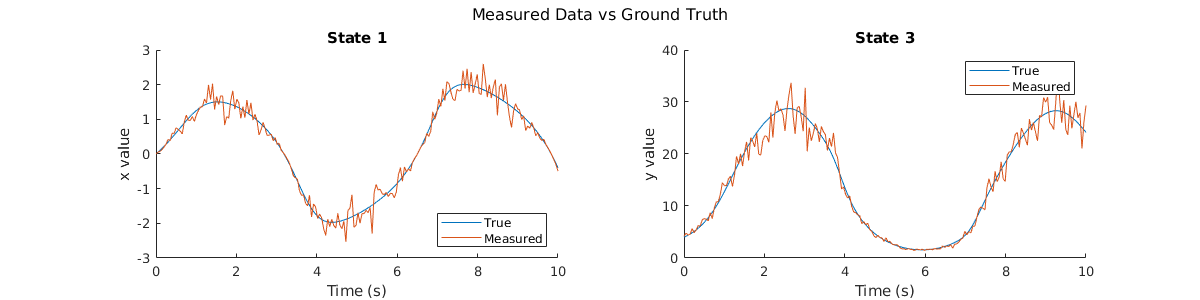

figure();
set(gcf, 'Position', [0, 0, 1200, 300])
sgtitle("Measured Data vs Ground Truth")

subplot(1, 2, 1);
hold on
plot(v_times, x_true);
plot(v_times, x_noisy);
title("State 1")
xlabel("Time (s)");
ylabel("x value");
legend("True", "Measured", 'location', 'se')

subplot(1, 2, 2);
hold on
plot(v_times, y_true.^2);
plot(v_times, y_noisy);
title("State 3")
xlabel("Time (s)");
ylabel("y value");
legend("True", "Measured")

### EKF Filtering Results

test_filter(ekf, v_times, mat_states_true, mat_meas_noisy);

Filter rate: 1186.85Hz

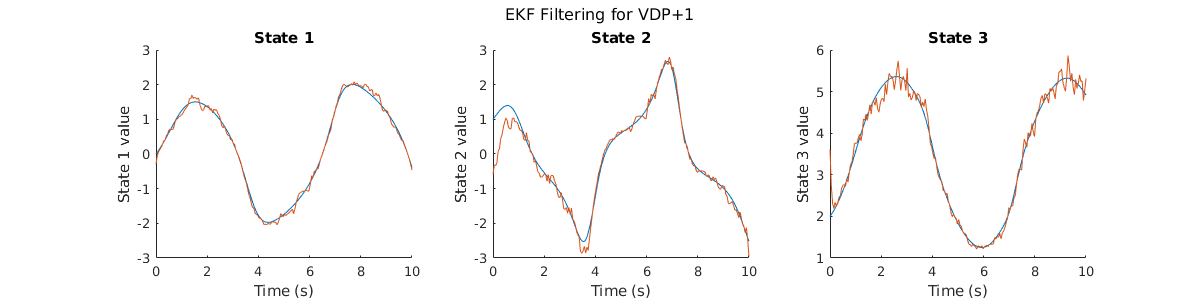

sgtitle("EKF Filtering for VDP+1")

### UKF Filtering Results

test_filter(ukf, v_times, mat_states_true, mat_meas_noisy);

Filter rate: 977.45Hz

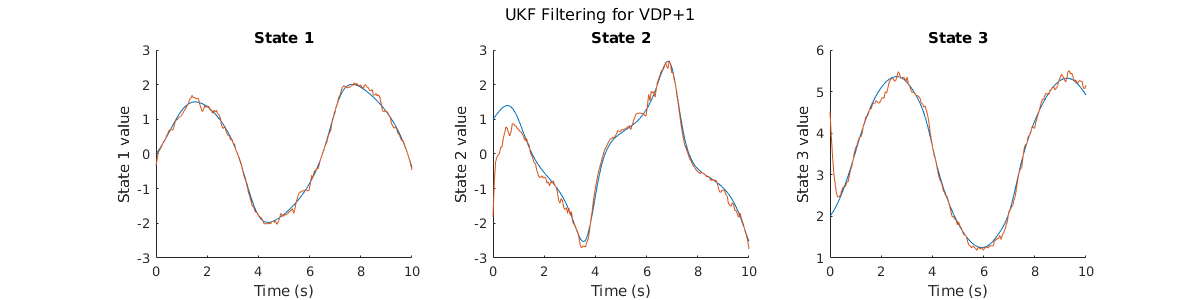

sgtitle("UKF Filtering for VDP+1")

function rates = rate_func(~, states)
rates = zeros(3, 1);
rates(1) = states(2);
rates(2) = (1-states(1)^2)*states(2)-states(1);
rates(3) = states(1) + sin(states(2));
end

function x = filter_test_state(x, wk) 
dt = 0.05; % [s] Sample time

x = x + dt*rate_func(0, x) + wk;
end

%% State Transition Jacobian Matrix
% Found by taking the Jacobian of the discrete state transition
% If the State Transition noise was non-additive this would have to return
% two outputs.
function [dfdx, dfdw] = filter_test_state_jacobian(xk, ~) 
dt = 0.05; % [s] Sample time
dfdx = [1                      dt                0 ;
        dt*(-1-2*xk(1)*xk(2))  1+dt*(1-xk(1)^2)  0 ; 
        dt                     dt*cos(xk(2))     1];

dfdw = eye(3);
end

function yk = filter_test_meas(xk, vk)
% Measurement function
yk = zeros(2, 1);
yk(1) = xk(1)*(1+vk(1));
yk(2) = xk(3)^2*(1+vk(2));
end

%% Measuremet Jacobian function
% Because the measurement noise is non-additive, this returns two outputs:
% The jacobian of the measuremetn function w.r.t the states, and w.r.t the noises.
function [dhdx, dhdv] = filter_test_meas_jacobian(xk, ~)
% dH/dx: Jacobian of the measurement function wrt the states
dhdx = [1 0 0;
        0 0 2*xk(3)];

% dH/dv: Jacobian of the measurement function wrt the noises
dhdv = [xk(1), 0;
        0,     xk(3)];
end

%% Filter testing function
function test_filter(filter, v_times, mat_states_true, mat_meas_noisy)
mat_residuals = zeros(size(mat_meas_noisy));
mat_state_corrected = zeros(size(mat_states_true));
mat_state_predicted = zeros(size(mat_states_true));

tic
for i = 1 : length(v_times)
    mat_residuals(i, :) = residual(filter, mat_meas_noisy(i, :));
    mat_state_corrected(i, :) = correct(filter, mat_meas_noisy(i, :));
    
    mat_state_predicted(i, :) = predict(filter);
end
elapsed_time = toc;
fprintf("Filter rate: %.2fHz", length(v_times)/elapsed_time);

figure();
set(gcf, 'Position', [0, 0, 1200, 300]);

states = size(mat_states_true, 2);
for i = 1 : states
    subplot(1, states, i);
    hold on;
    plot(v_times, mat_states_true(:, i));
    plot(v_times, mat_state_corrected(:, i));
    
    title(sprintf("State %d", i))
    xlabel("Time (s)")
    ylabel(sprintf("State %d value", i))
end

end